%clearing crap 
clear all
clf

%reading data
data = readtable("Work/BONDIFI/FTIR_data/Bondifi 100C FTIR normalised_220623.csv");

tit = "100^{o}C Normalised";
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 130C FTIR normalised_220623.csv");
% tit = "130^{o}C Normalised";
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 160C FTIR normalised_220623.csv");
% tit = "160^{o}C Normalised";

% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 100C FTIR 1510 fixed_230623.csv");
% tit = "100^{o}C 1505cm^{-1} fix";
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 130C FTIR 1510 fixed_230623.csv");
% tit = "130^{o}C 1505cm^{-1} fix";
data = readtable("Work/BONDIFI/FTIR_data/Bondifi 160C FTIR 1510 fixed_230623.csv");

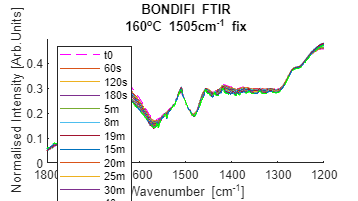

tit = "160^{o}C 1505cm^{-1} fix";

ncols = width(data); %extracting number of columns
colnames=data.Properties.VariableNames; %col names

data1 = table2array(data); %converting table2array

%looping through all columns
for n = 1:ncols-1
    
    name = string(colnames(n+1)); %etracting column name
    name = strrep(name,"x",""); %removing x's

    %changing first and last plot to be different
    if name=="t0"
        plot(data1(:,1),data1(:,n+1),"m--",'DisplayName',name);
        hold on %plotting on same graph
    %elseif name=="90m"
    elseif name=="2h"
        fig = plot(data1(:,1),data1(:,n+1),"g--",'DisplayName',name);
        hold on %plotting on same graph
    else
        plot(data1(:,1),data1(:,n+1),'DisplayName',name);
        hold on %plotting on same graph
    end
    
    hold on %plotting on same graph
end
hold off %end plotting
legend show
legend("location","northwest")

%plot limits
% xlim([500 4000])
xlim([1200 1800])

%labelling graph
title(["BONDIFI FTIR" tit])
xlabel("Wavenumber [cm^{-1}]");
ylabel("Normalised Intensity [Arb.Units]");

%beautifying curve
ax = gca;
box off;
set(gca, 'XDir','reverse') %inverting x axis

%export image size
set(gcf, 'Units', 'Pixels', 'Position', [0, 0, 1280, 720], 'PaperUnits', 'Inches', 'PaperSize', [7.25, 9.125])
saveas(fig,"C:\Users\Jack\Desktop\Alex\FTIR\output.png")

%100C replot with line
hold on %plotting on same graph

%focus for FTIR 100 data
% xline(3012.27,"--")
% xline(3377.23,"--")
% xline(1632.93,"--")
% xline(1075.12,"--")
% xline(923.25,"--")
% xline(895.77,"--")
% xlim([1550 1700])
% ylim([0.7 1.2])
% xlim([1050 1100])
% ylim([1.66 1.78])

%focus for FTIR 160 data
xline(3367.59,"--",'DisplayName',"3367.59")
xline(2925.97,"--",'DisplayName',"2925.97")
xline(2856.06,"--",'DisplayName',"2856.06")
xline(2156.03,"--",'DisplayName',"2156.03")
xline(1974.75,"--",'DisplayName',"1974.75")
xline(1743.82,"--",'DisplayName',"1743.82")
xline(1627.63,"--",'DisplayName',"1627.63")
xline(1510.47,"--",'DisplayName',"1510.47")
xline(1030.77,"--",'DisplayName',"1030.77")

% xlim([1675 1775])
% ylim([.15 .24])

% xlim([1575 1700])
% ylim([.25 .34])

% xlim([1500 1520])
% ylim([.27 .3])

xlim([975 1100])
ylim([.6 1.1])

hold off

%just plotting t0 and 2h
%clearing crap 
clear all
clf

%reading data
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 100C FTIR normalised_220623.csv");
% tit = "100 C";
% % data = readtable("Work/BONDIFI/FTIR_data/Bondifi 130C FTIR normalised_220623.csv");
% % tit = "130 C";
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 160C FTIR normalised_220623.csv");
% tit = "160 C";

data = readtable("Work/BONDIFI/FTIR_data/Bondifi 100C FTIR 1510 fixed_230623.csv");
tit = "100 C";
% data = readtable("Work/BONDIFI/FTIR_data/Bondifi 130C FTIR 1510 fixed_230623.csv");
% tit = "130 C";
data = readtable("Work/BONDIFI/FTIR_data/Bondifi 160C FTIR 1510 fixed_230623.csv");
tit = "160 C";

ncols = width(data); %extracting number of columns
colnames=data.Properties.VariableNames; %col names

data1 = table2array(data); %converting table2array

for n = 1:ncols-1

    name = string(colnames(n+1)); %etracting column name
    name = strrep(name,"x",""); %removing x's
    
    if name=="t0"|name=="2h"
        plot(data1(:,1),data1(:,n+1),'DisplayName',name);
    end
    
    
    hold on %plotting on same graph
end

hold off %end plotting
legend show
legend("location","northwest")

%labelling graph
title(["BONDIFI FTIR" tit])
xlabel("Wavenumber [cm^{-1}]");
ylabel("Normalised Intensity [Arb.Units]");

%beautifying curve
ax = gca;
box off;
set(gca, 'XDir','reverse') %inverting x axis